# HINF

clear
ang_Lin=88;

addpath("../../controllers/"); 
load("../../controllers/data/TF.mat");

[SS,TF]=FoundTF(ang_Lin);
TF

TF =
 
         0.9745
  ---------------------
  s^2 + 3.334 s + 1.791
 
Continuous-time transfer function.



SS

SS =
 
  A = 
           theta   omega
   theta       0       1
   omega  -1.791  -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



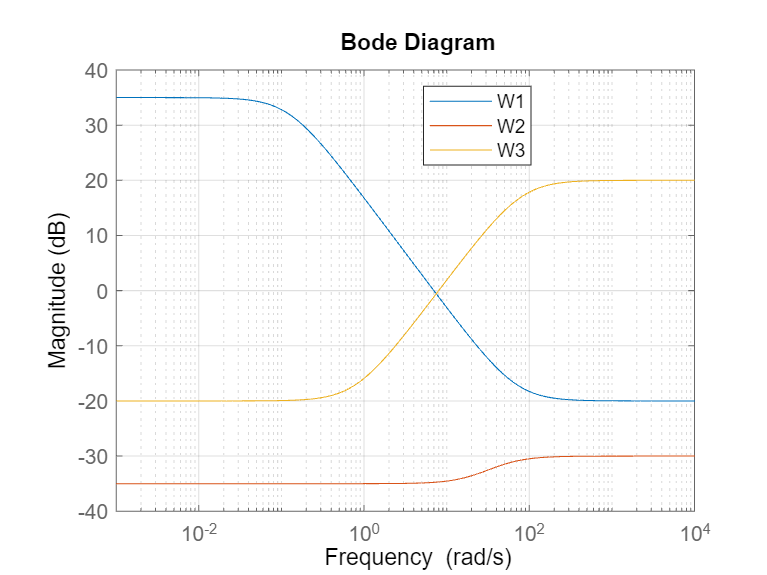


%[A,B,C,D]=tf2ss(cell2mat(TF.Numerator),cell2mat(TF.Denominator));
%G=ss(A,B,C,D);
G= SS;
USSlinmodel = createUSSmodel(G,20);

freqC1=7;freqC2=32;freqC3=8;
W1 = makeweight(db2mag(35),[freqC1 db2mag(0)],db2mag(-20));
W2 = makeweight(db2mag(-35),[freqC2 db2mag(-32.5)],db2mag(-30));
W3 = makeweight(db2mag(-20),[freqC3 db2mag(0)],db2mag(20));
bodemag(W1,W2,W3)

legend
legend("Location","best")
grid on


[K_hinf,CL,gamma] = mixsyn(G,W1,W2,W3);
gamma

gamma = 1.4483

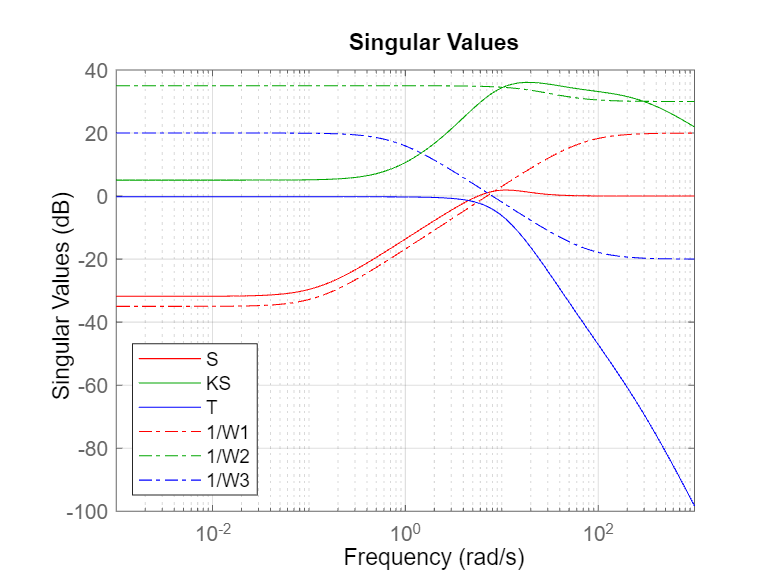

S = feedback(1,G*K_hinf);KS = K_hinf*S;T = 1-S;
sigma(S,'r',KS,'g',T,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

ALL W

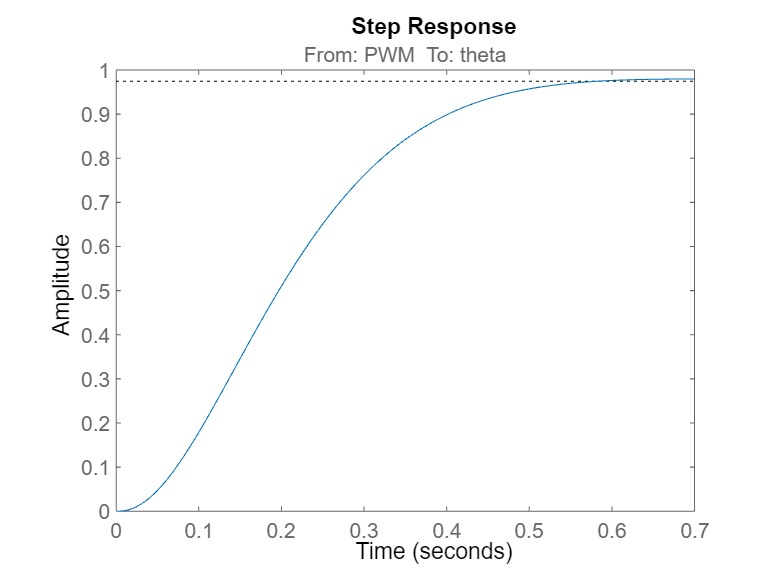

figure()
[K_hinf,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_hinf,G);
GCL=feedback(OL,1);
GCL.InputName="PWM";
step(GCL)

stepinfo(GCL)

ans = struct with fields:
         RiseTime: 0.3064
    TransientTime: 0.4932
     SettlingTime: 0.4932
      SettlingMin: 0.8823
      SettlingMax: 0.9795
        Overshoot: 0.5366
       Undershoot: 0
             Peak: 0.9795
         PeakTime: 0.6960


AnchoBanda=bandwidth(GCL)/(2*pi)

AnchoBanda = 1.1161

### Incertidumbre

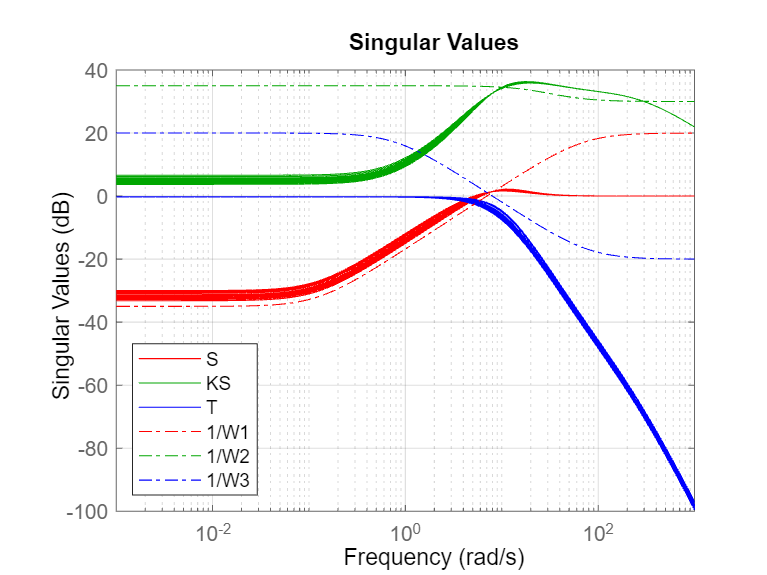

SUSS = feedback(1,USSlinmodel*K_hinf);
KSSUSS = K_hinf*SUSS;
TSUSS = 1-SUSS;
sigma(SUSS,'r',KSSUSS,'g',TSUSS,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

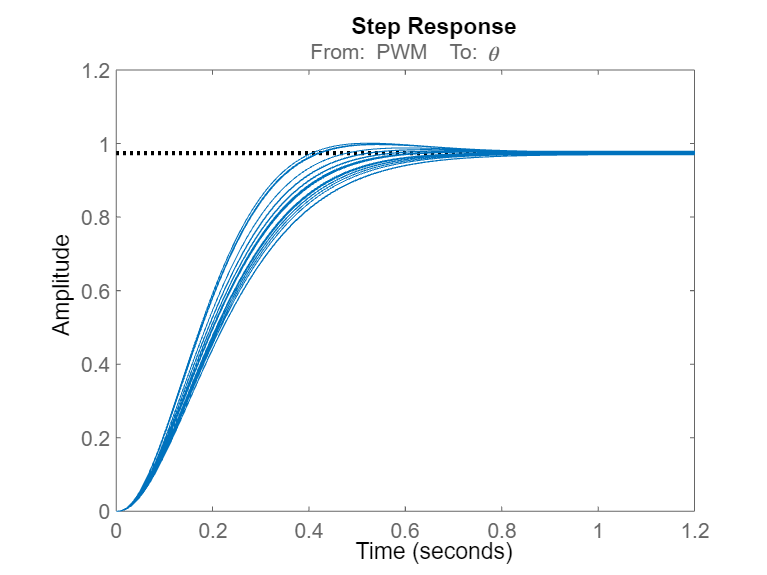


OLlinUSS=series(K_hinf,USSlinmodel);
GCLlinUSS=feedback(OLlinUSS,1);
GCLlinUSS.InputName="PWM";
GCLlinUSS.OutputName="\theta";
step(GCLlinUSS)
%axis([0 1.2 0 1.2])
hold off

bandwidth(GCLlinUSS)/2/pi

ans = 1.1161

stepinfo(GCLlinUSS)

ans = struct with fields:
         RiseTime: 0.3064
    TransientTime: 0.4932
     SettlingTime: 0.4932
      SettlingMin: 0.8823
      SettlingMax: 0.9795
        Overshoot: 0.5366
       Undershoot: 0
             Peak: 0.9795
         PeakTime: 0.6960


## Simulación Sistema Lineal

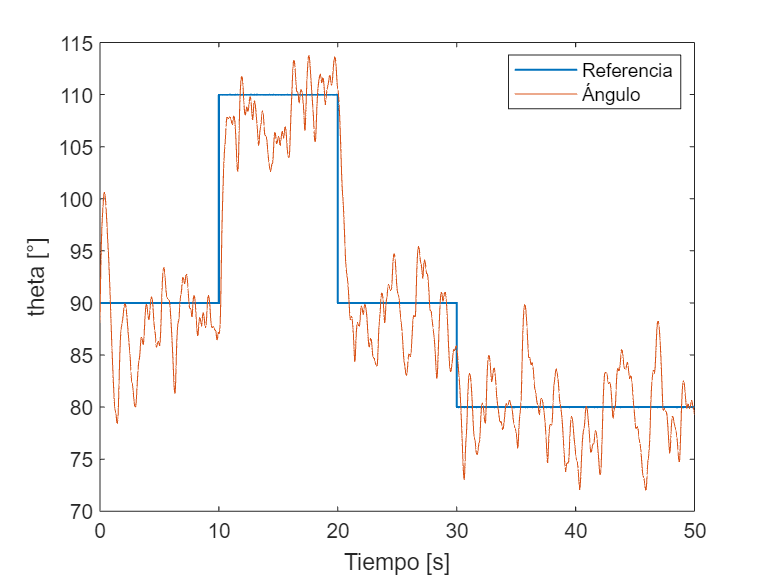

results = sim("hinfSL.slx",50); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
legend('Referencia', 'Ángulo','Location','best');

## Simulación Sistema No Lineal

DirectCMD = 40;
results = sim("hinfNL.slx",50); 

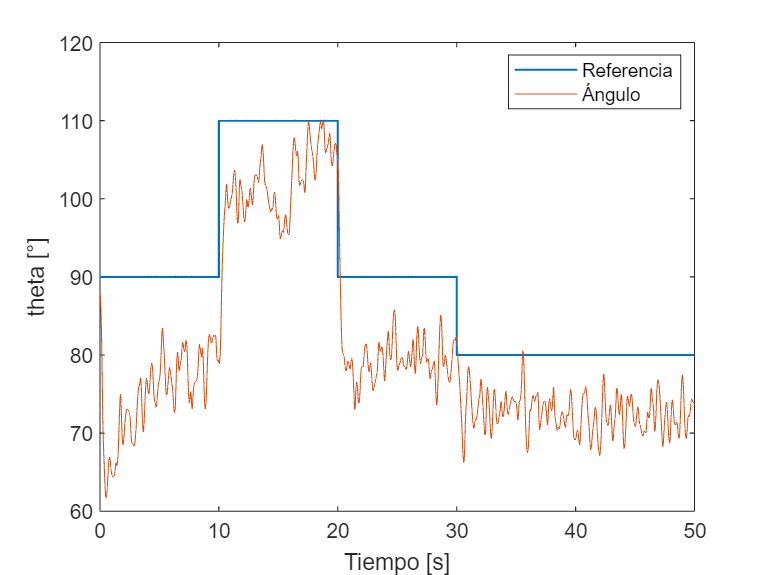


t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
ylim([60 120])
legend('Referencia', 'Ángulo','Location','best');

## Implementación Arduino

K_hinf

K_hinf =
 
  A = 
               x1          x2          x3          x4          x5
   x1     -0.1239           0           0           0           0
   x2        6470      -123.2      -47.42       -2730      -200.4
   x3  -2.591e-13   3.798e-15         -80          32   7.735e-15
   x4  -4.399e-13   6.449e-15   4.494e-15   1.852e-13           1
   x5        6305      -78.51      -46.22       -2662      -198.6
 
  B = 
              u1
   x1          2
   x2  2.053e-18
   x3  1.829e-15
   x4  3.106e-15
   x5  3.697e-15
 
  C = 
           x1      x2      x3      x4      x5
   y1    6470  -80.56  -47.42   -2730  -200.4
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



K_hinf_TF = tf(K_hinf)

K_hinf_TF =
 
  1.294e04 s^4 + 1.631e06 s^3 + 4.949e07 s^2 + 1.501e08 s + 7.912e07
  ------------------------------------------------------------------
  s^5 + 402 s^4 + 3.72e04 s^3 + 1.032e06 s^2 + 9.29e06 s + 1.135e06
 
Continuous-time transfer function.



K_hinf_TF_Discrete = c2d(K_hinf_TF,2.5e-3,'tustin')

K_hinf_TF_Discrete =
 
  12.04 z^5 - 32.62 z^4 + 17.32 z^3 + 23.84 z^2 - 29.36 z + 8.782
  ---------------------------------------------------------------
     z^5 - 4.2 z^4 + 6.966 z^3 - 5.685 z^2 + 2.273 z - 0.3543
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



function [USSmodel] = createUSSmodel(linmodel,Delta)
% Create a new SS model with 5% uncertainty for each element of A,B,C and D

% Get the dimensions of A,B,C and D
[n,m] = size(linmodel.B);
[p,n] = size(linmodel.C);

% Create a ureal object with 5% uncertainty

% Iterate over each element of A,B,C and D and add uncertainty
for i=1:n
    for j=1:n
        if linmodel.A(i,j)~=0
            A(i,j) = ureal(['A' num2str(i) num2str(j)],linmodel.A(i,j),'Percentage',Delta);
            else
            A(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.B(i,j)~=0
            B(i,j) = ureal(['B' num2str(i) num2str(j)],linmodel.B(i,j),'Percentage',Delta);
            else
            B(i,j)=0;
        end
    end
end

for i=1:p
    for j=1:n
        if linmodel.C(i,j)~=0
            C(i,j) = ureal(['C' num2str(i) num2str(j)],linmodel.C(i,j),'Percentage',Delta);
            else
            C(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.D(i,j)~=0
            D(i,j) = ureal(['D' num2str(i) num2str(j)],linmodel.D(i,j),'Percentage',Delta);
        else
            D(i,j)=0;
        end
    end
end

% Create a USS model
USSmodel = uss(ss(A,B,C,D));

end


% function [Gss, G, Gnum, Gden] =FoundTF(thetap)
% %Pesos [N]
% wb=0.105948;
% wcp= 0.014145;
% wm=0.030411; 
% 
% %Distancias [m]
% d1=130.75e-3;
% d2=50.75e-3;
% e=41.91e-3;
% 
% %Momento de inercia [kg-m^2]
% I=15e-5; 
% 
% %Coeficiente término \theta
% Coeficiente = wcp*d2-wm*d1-wb*e;
% 
% %Constante del motor
% km=0.00118;
% 
% %Constante de Fricción
% beta = 1.667;
% miu=beta*2*I;
% 
% %TransferFunction
% s=tf('s');
% c = (((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap)));
% G=((km*d1)/I)/((s^2)+(miu/I)*s+(((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap))));
% 
% 
% Gnum = cell2mat(G.Numerator);
% Gden = cell2mat(G.Denominator);
% 
% %Parametros del motor
% DZ = 3;
% MAX_PWM = 80;
% 
% %Variables de estado
% ass = (km*d1)/I;
% bss = (wcp*d2-wm*d1-wb*e)/I;
% css = miu/I;
% A = [0 1; bss*cosd(thetap) -css];
% B = [0 ass]';
% C = [0 1];
% D = [0];
% 
% Gss = ss(A,B,C,D);
% Gss.StateName= {'Velocity','Position'};
% Gss.OutputName= {'Position'};
% 
% end